# Setup

A = zeros(33);
b = zeros(33,1);
ambient = 20;
[A,b] = discretisation(A,b,ambient);

## Full Storage

trials = 20;
time1 = tic;

for i = 1:trials
    A1 = cholesky_factorisation(A);
    X1 = forward_substitution(A1', b);
    X1 = backward_substitution(A1, X1);
end

avg_time_taken1 = toc(time1)/trials;
% Memory
whos A1

  Name       Size            Bytes  Class     Attributes

  A1        33x33             8712  double              



mem1 = 8712;
% Runtime
avg_time_taken1

avg_time_taken1 = 0.0027

% Floating point operations
flops1 = 0;
[A1, flops1] = cholesky_factorisation_flops(A, flops1);
[X1, flops1] = forward_substitution_flops(A1', b, true, flops1);
[X1, flops1] = backward_substitution_flops(A1, X1, true, flops1);
flops1

flops1 = 14707

## Packed Storage

trials = 20;
time2 = tic;

for i = 1:trials
    A_packed = A(triu(true(size(A))))'; % row packed
    A2 = cholesky_factorisation_packed(A_packed);
    X2 = forward_substitution_rowpacked(A2', b);
    X2 = backward_substitution_rowpacked(A2, X2);
end

avg_time_taken2 = toc(time2)/trials;

% Memory
whos A2

  Name      Size             Bytes  Class     Attributes

  A2        1x561             4488  double              



mem2 = 4488;
% Runtime
avg_time_taken2

avg_time_taken2 = 7.5635e-04

% Floating point operations
flops2 = 0;
[A2, flops2] = cholesky_factorisation_packed_flops(A_packed, flops2);
[X2, flops2] = forward_substitution_rowpacked_flops(A2', b, flops2);
[X2, flops2] = backward_substitution_rowpacked_flops(A2, X2, flops2);
flops2

flops2 = 14707

## Band Storage

trials = 20;
time3 = tic;

for i = 1:trials
    RCM_order = symrcm(A);
    A_RCM = A(RCM_order,RCM_order);
    b_RCM = b(RCM_order);
    
    [p,q] = bandwidth(A_RCM);
    A_band = zeros(p+1,33);
    
    for ii = p+1:-1:1
        A_band(ii,:) = cat(1,zeros(p+1-ii,1),diag(A_RCM,p+1-ii));
    end
    
    A_band_CHOL = cholesky_factorisation_band(A_band);
    z_RCM = forward_substitution_band(A_band_CHOL',b_RCM);
    x_RCM = backward_substitution_band(A_band_CHOL,z_RCM);
end

avg_time_taken3 = toc(time3)/trials;

X3 = ones(33,1);
for  i = 1:33
    X3(RCM_order(i)) = x_RCM(i);
end

% Fill-in
nz = sum(A(:)~=0);
chol_A = A_band_CHOL;
nz_chol = sum(chol_A(:)~=0);

fill_in = nz_chol - nz

fill_in = 27

fill_in_percentage = fill_in/nz

fill_in_percentage = 0.1915

% Memory
whos A_band_CHOL

  Name             Size            Bytes  Class     Attributes

  A_band_CHOL      7x33             1848  double              



mem3 = 1848;
% Runtime
avg_time_taken3

avg_time_taken3 = 7.0785e-04

% Floating point operations
flops3 = 0;
[A_band_CHOL, flops3] = cholesky_factorisation_band_flops(A_band, flops3);
[z_RCM, flops3] = forward_substitution_band_flops(A_band_CHOL', b_RCM, true, flops3);
[x_RCM, flops3] = backward_substitution_band_flops(A_band_CHOL, z_RCM, true, flops3);
flops3

flops3 = 2188

## Sparse Storage

trials = 20;
time4 = tic;

for i = 1:trials
    A_Sparse = sparse(A);
    p = symamd(A_Sparse); % permutation vector for AMD
    S = A_Sparse(p,p); % permute A

    A4 = cholesky_factorisation_sparse(S);
    X4 = forward_substitution(A4', b(p));
    X4 = backward_substitution(A4, X4);

    p_inv(p) = 1:length(p); % inverse of permatation
    X4 = X4(p_inv);
end

avg_time_taken4 = toc(time4)/trials;

% Bandwidth
Bandwidth_A_Sparse = bandwidth(A_Sparse)

Bandwidth_A_Sparse = 6

Bandwidth_S = bandwidth(S)

Bandwidth_S = 29

% Fill-in
nz = sum(A(:)~=0);
chol_A = A4;
nz_chol = sum(chol_A(:)~=0);

fill_in = nz_chol - nz

fill_in = -1

fill_in_percentage = fill_in/nz

fill_in_percentage = -0.0071

% Memory
whos A_Sparse

  Name           Size            Bytes  Class     Attributes

  A_Sparse      33x33             2528  double    sparse    



whos S

  Name       Size            Bytes  Class     Attributes

  S         33x33             2528  double    sparse    



mem4 = 2528;
% Runtime
avg_time_taken4

avg_time_taken4 = 0.0187

% Floating point operations
flops4 = 0;
[A4, flops4] = cholesky_factorisation_sparse_flops(S, flops4);
[X4, flops4] = forward_substitution_flops(A4', b(p), true, flops4);
[X4, flops4] = backward_substitution_flops(A4, X4, true, flops4);
flops4

flops4 = 5207

## CSR Storage

[A_csr, C, Rb] = CSR_Storage_method(A);
tol = 1e-6;
maxiters = 2000;
x0 = ones(size(b));

% Jacobi
trials = 20;
time_jacobi = tic;

for i = 1:trials
    [X5, converged1, k1, res_vec1] = CSR_Jacobi(A_csr,C,Rb,x0,tol,maxiters,b);
end

avg_time_taken_J = toc(time_jacobi)/trials;

% Gauss Siedel
time_GS = tic;

for i = 1:trials
    [X6, converged2, k2, res_vec2] = CSR_gauss_seidel(A_csr,C,Rb,b,x0,tol,maxiters);
end
avg_time_taken_GS = toc(time_GS)/trials;

% Succession Over Relaxation
time_SOR = tic;
omega = 1.6065;

for i = 1:trials
    [X7, converged3, k3, res_vec3] = CSR_SOR(A_csr,C,Rb,b,x0,tol,maxiters,omega);
end
avg_time_taken_SOR = toc(time_SOR)/trials;

% Conjugate Gradient
time_CG = tic;

for i = 1:trials
    [X8, converged4, k4, res_vec4] = CSR_Conjugate_Gradient(A_csr,C,Rb,b',x0,tol,maxiters);
end

avg_time_taken_CG = toc(time_CG)/trials;

% Memory
whos A_csr C Rb

  Name       Size             Bytes  Class     Attributes

  A_csr      1x141             1128  double              
  C          1x141             1128  double              
  Rb         1x34               272  double              



mem5 = 1128;
% Iterations
k1 % Number of iterations for the Jacobi with CSR implementation method

k1 = 396

k2 % Number of iterations for the Gauss Siedel with CSR implementation method

k2 = 2000

k3 % Number of iterations for the Succession over relaxation with CSR implementation method

k3 = 35

k4 % Number of iterations for the Conjugate Gradient with CSR implementation method

k4 = 24

% Runtime
avg_time_taken_J % average runtime for the Jacobi with CSR implementation method

avg_time_taken_J = 0.0160

avg_time_taken_GS % average runtime for the Gauss Siedel with CSR implementation method

avg_time_taken_GS = 0.0650

avg_time_taken_SOR % average runtime for the Jacobi with CSR implementation method

avg_time_taken_SOR = 0.0028

avg_time_taken_CG % average runtime for the Conjugate Gradient with CSR implementation method

avg_time_taken_CG = 0.0012

% Floating point operations
flopsJ = 0;
[X5, converged1, k1, res_vec1, flopsJ] = CSR_Jacobi_flops(A_csr,C,Rb,x0,tol,maxiters,b,flopsJ);
flopsJ

flopsJ = 223627

flopsGS = 0;
[X6, converged2, k2, res_vec2, flopsGS] = CSR_gauss_seidel_flops(A_csr,C,Rb,b,x0,tol,maxiters,flopsGS);
flopsGS

flopsGS = 1130283

flopsSOR = 0;
[X7, converged3, k3, res_vec3, flopsSOR] = CSR_SOR_flops(A_csr,C,Rb,b,x0,tol,maxiters,omega,flopsSOR);
flopsSOR

flopsSOR = 22368

flopsCG = 0;
[X8, converged4, k4, res_vec4, flopsCG] = CSR_Conjugate_Gradient_flops(A_csr,C,Rb,b',x0,tol,maxiters,flopsCG);
flopsCG

flopsCG = 14085

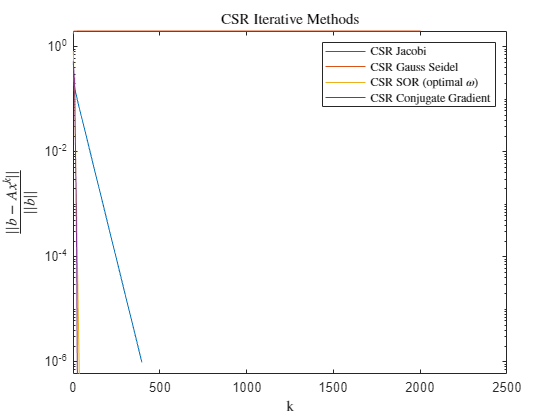

% For sparse matricies of size n x n each iterative method with CSR- 
% implementation have an O(n) flops compared to an O(n^2) flops for the direct methods  

% Residual norm against iterations plot x4
figure
semilogy(res_vec1)
hold on
semilogy(res_vec2)
semilogy(res_vec3)
semilogy(res_vec4)
xlabel('k', 'Interpreter',"latex")
ylabel('$\frac{||b-Ax^{k}||}{||b||}$', "Interpreter", "latex")
legend('CSR Jacobi', 'CSR Gauss Seidel', 'CSR SOR (optimal $\omega$)', 'CSR Conjugate Gradient',"Interpreter", "latex")
title("CSR Iterative Methods", "Interpreter","latex")

% Tolerance for visually indistinguishable x4

[X5_, converged1_, k1_, res_vec1_] = CSR_Jacobi(A_csr,C,Rb,x0,tol,maxiters,b);
[X6_, converged2_, k2_, res_vec2_] = CSR_gauss_seidel(A_csr,C,Rb,b,x0,tol,maxiters);
[X7_, converged3_, k3_, res_vec3_] = CSR_SOR(A_csr,C,Rb,b,x0,tol,maxiters,omega);
[X8_, converged4_, k4_, res_vec4_] = CSR_Conjugate_Gradient(A_csr,C,Rb,b',x0,tol,maxiters);
[DX5, Dconverged1, Dk1, Dres_vec1] = jacobi(A,b,x0,tol,maxiters);
[DX6, Dconverged2, Dk2, Dres_vec2] = gauss_seidel(A,b,x0,tol,maxiters);
[DX7, Dconverged3, Dk3, Dres_vec3] = SOR(A,b,x0,tol,maxiters,omega);
[DX8, Dconverged4, Dk4, Dres_vec4] = Conjugate_Gradient(A,b,x0,tol,maxiters);

X5_

X5_ =    53.6688
   52.9050
   51.4012
   49.2175
   46.4683
   43.3277
   54.4326
   53.6451
   52.0812
   49.7830


DX5

DX5 =    53.6688
   52.9050
   51.4012
   49.2175
   46.4683
   43.3277
   54.4326
   53.6451
   52.0812
   49.7830


X6_

X6_ =    53.6692
   52.9054
   51.4015
   49.2178
   46.4685
   43.3278
   54.4329
   53.6455
   52.0815
   49.7832


DX6

DX6 =    53.6688
   52.9050
   51.4012
   49.2175
   46.4684
   43.3277
   54.4326
   53.6451
   52.0812
   49.7830


X7_

X7_ =    53.6690
   52.9053
   51.4015
   49.2177
   46.4685
   43.3277
   54.4328
   53.6454
   52.0814
   49.7832


DX7

DX7 =    53.6690
   52.9053
   51.4015
   49.2177
   46.4685
   43.3277
   54.4328
   53.6454
   52.0814
   49.7832


X8_

X8_ =    53.6692
   52.9054
   51.4015
   49.2178
   46.4686
   43.3278
   54.4329
   53.6455
   52.0815
   49.7832


DX8

DX8 =    53.6692
   52.9054
   51.4015
   49.2178
   46.4686
   43.3278
   54.4329
   53.6455
   52.0815
   49.7832


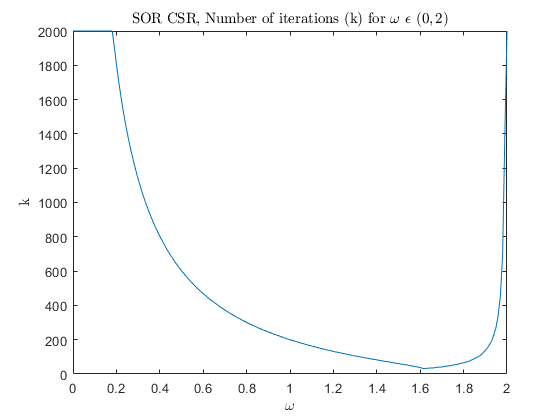

% For any tolerance The CSR methods are vissually indistinguasable from
% the direct methods for at least the first 10 elements in each vector.

% Investiate omega for SOR
% Include plot of omega against number of iterations required to converge to tolerance
omega_vec = linspace(1e-4,2,200);
number_iterations = 1:length(omega_vec);

for i = 1:length(omega_vec)
    [X7, converged3, k3, res_vec3] = CSR_SOR(A_csr,C,Rb,b,x0,tol,maxiters,omega_vec(i));
    number_iterations(i) = k3;
end

figure
plot(omega_vec,number_iterations)
hold on
title('SOR CSR, Number of iterations (k) for $\omega \ \epsilon \ (0,2)$', 'Interpreter',"latex")
xlabel("$\omega$","Interpreter","latex")
ylabel("k","Interpreter","latex")

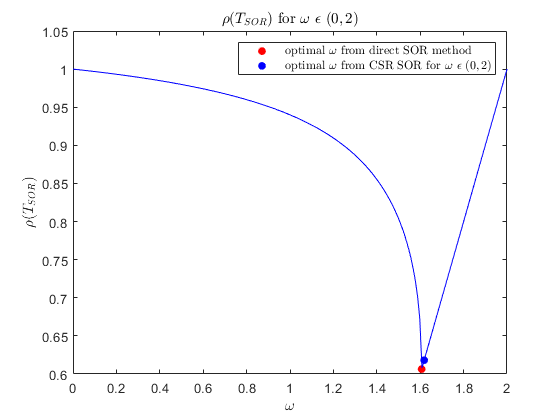

D = diag(diag(A));
U = zeros(length(b));
for i = 1:length(b)
    for j = i+1:length(b)
        U(i,j) = A(i,j);
    end
end

rho_vec = zeros(length(omega_vec),1);

for i = 1:length(omega_vec)
    T = (D/omega_vec(i) + U') \ ((1 - omega_vec(i)) / omega_vec(i) * D - U);
    rho_vec(i) = max(abs(eig(T)));
end

T_j = -D \ (U' + U);
rho_Tj = max(abs(eig(T_j)));

omega_opt = 2 / (1 + sqrt(1 - rho_Tj^2));
T_opt = (D/omega_opt + U') \ ((1 - omega_opt) / omega_opt * D - U);
rho_opt = max(abs(eig(T_opt)));

figure
plot(omega_opt,rho_opt,'r.','MarkerSize',20)
hold on
[val,idx] = min(number_iterations);
plot(omega_vec(idx),rho_vec(idx),'b.', 'MarkerSize',20)
plot(omega_vec,rho_vec,'b')
title('$\rho(T_{SOR})$ for $\omega \ \epsilon \ (0,2)$', "Interpreter","latex")
xlabel("$\omega$","Interpreter","latex")
ylabel("$\rho(T_{SOR})$","Interpreter","latex")
legend('optimal  $\omega$ from direct SOR method','optimal $\omega$ from CSR SOR for $\omega \ \epsilon \ (0,2)$',"Interpreter", "latex")

% Does formula for optimal omega hold

The formula that is used to calculate the optimal omega value for the succession over relaxation method holds as the matrix A is obtained from computing finite difference equations to create a discretisation for the laplace equation $\nabla^2 T=0$ which allows use to implement the formula:


$$\omega_{\mathrm{opt}} =\frac{2}{1+\sqrt{1-{\rho \left(T_J \right)}^2 }}$$
 

## Efficiency Comparison

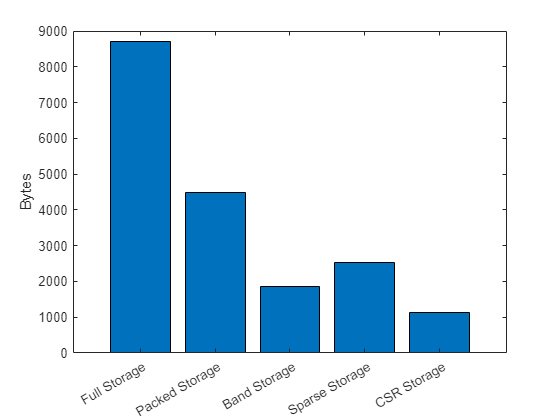

% Memory graph
names = categorical({'Full Storage','Packed Storage','Band Storage','Sparse Storage','CSR Storage'});
names = reordercats(names,{'Full Storage','Packed Storage','Band Storage','Sparse Storage','CSR Storage'});
figure
bar(names, [mem1 mem2 mem3 mem4 mem5])
ylabel('Bytes')

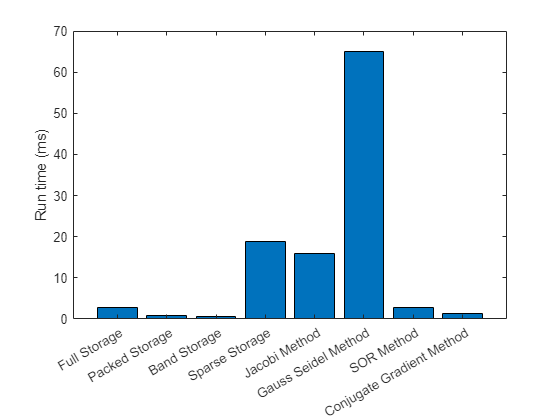

% Run time graph
names = categorical({'Full Storage','Packed Storage','Band Storage','Sparse Storage','Jacobi Method','Gauss Seidel Method','SOR Method','Conjugate Gradient Method'});
names = reordercats(names,{'Full Storage','Packed Storage','Band Storage','Sparse Storage','Jacobi Method','Gauss Seidel Method','SOR Method','Conjugate Gradient Method'});
figure
bar(names, [avg_time_taken1 avg_time_taken2 avg_time_taken3 avg_time_taken4 avg_time_taken_J avg_time_taken_GS avg_time_taken_SOR avg_time_taken_CG]*1000)
ylabel('Run time (ms)')

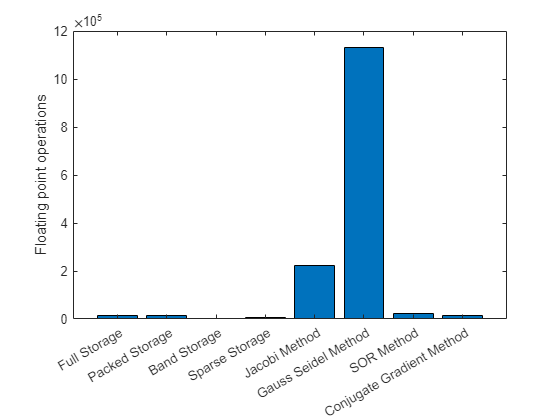

% Floating point operation counts
figure
bar(names, [flops1 flops2 flops3 flops4 flopsJ flopsGS flopsSOR flopsCG])
ylabel('Floating point operations')

## Visualisation

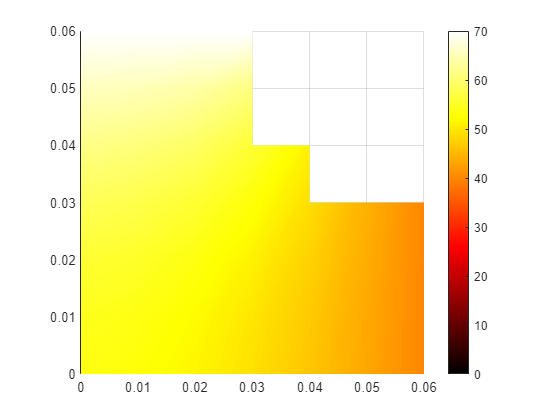

T = zeros(7);
T(7,1:6) = X1(1:6);
T(7,7) = 40;
T(6,1:6) = X1(7:12);
T(6,7) = 40;
T(5,1:6) = X1(13:18);
T(5,7) = 40;
T(4,1:6) = X1(19:24);
T(4,7) = 40;
T(3,1:5) = X1(25:29);
T(3,6) = nan;
T(2,1:4) = X1(30:33);
T(2,5:6) = nan;
T(1,1:4) = 70;

[X,Y] = meshgrid(0:0.01:0.06, 0.06:-0.01:0);

figure
surf(X, Y, T)
view(2) % 2-dimensional (top-down) view
shading interp
colormap hot
colorbar
axis image

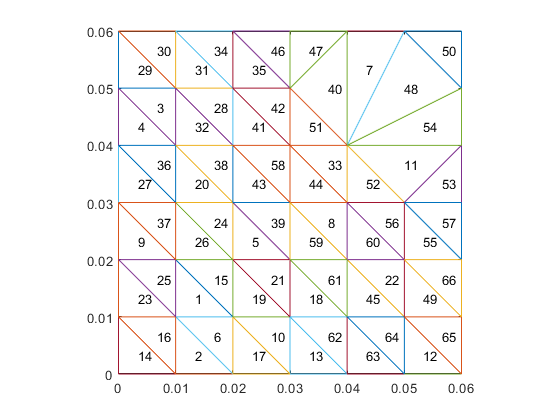


temperatures = T(~isnan(T));
x = X(~isnan(T));
y = Y(~isnan(T));
tri = delaunay(x, y);
figure
trimesh(tri, x, y)
axis image

for i = 1:size(tri,1)
    indices = tri(i,:);
    vertices = [x(indices) y(indices)];
    centroid = mean(vertices);
    text(centroid(1), centroid(2), sprintf('%g',i));
end

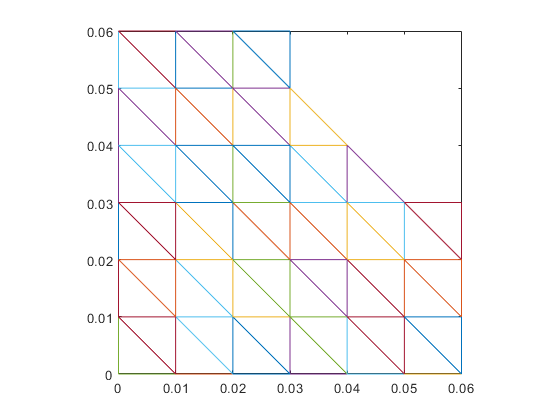

tri([7,11,40,47,48,50,53,54],:) = [];
figure
trimesh(tri, x, y)
axis image

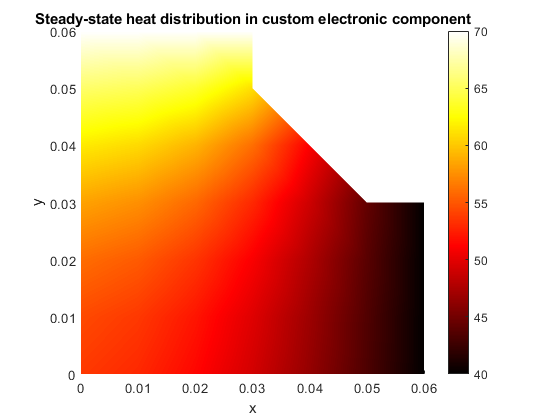


figure
trisurf(tri, x, y, temperatures)
view(2) % 2-dimensional (top-down) view
shading interp
colormap hot
colorbar
caxis([40 70])
xlabel('x')
ylabel('y')
title('Steady-state heat distribution in custom electronic component')
axis image
grid off

min_temp = min(X1)

min_temp = 43.3278

max_temp = max(X1)

max_temp = 65.5334

## Effect Of Ambient Temperature

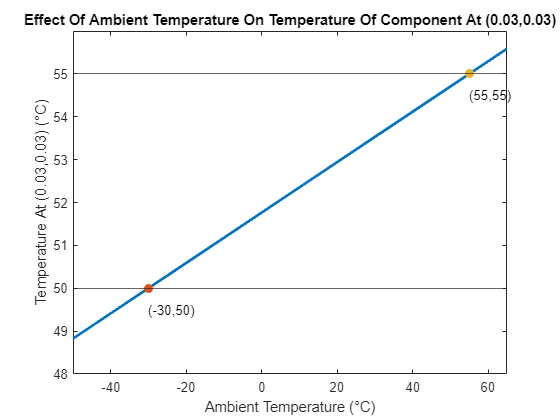

%
X22_vec = zeros(1,116);
for ambient = -50:65
    [A,b] = discretisation(A,b,ambient);
    % Full storage
    A1 = cholesky_factorisation(A);
    X1 = forward_substitution(A1', b);
    X1 = backward_substitution(A1, X1);
    X22_vec(ambient+51) = X1(22);
end

figure
plot(-50:65, X22_vec,'LineWidth',2)
hold on
yline(50)
yline(55)
xlim([-50,65])
yticks(48:1:55)
xlabel('Ambient Temperature (°C)')
ylabel('Temperature At (0.03,0.03) (°C)')
title('Effect Of Ambient Temperature On Temperature Of Component At (0.03,0.03)')

plot(-30,50,'.','MarkerSize',20)
text(-30,49.5,'(-30,50)')
plot(55,55,'.','MarkerSize',20)
text(55,54.5,'(55,55)')

## Extras

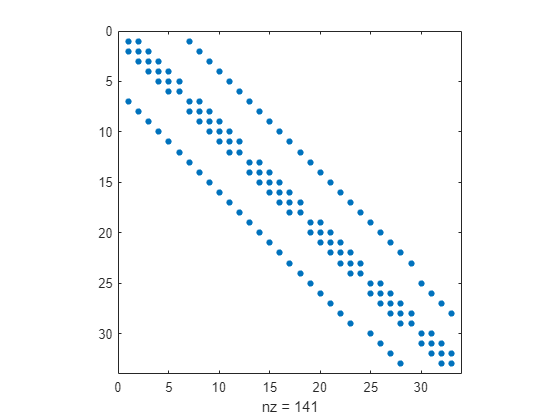

figure;spy(A);title('A')

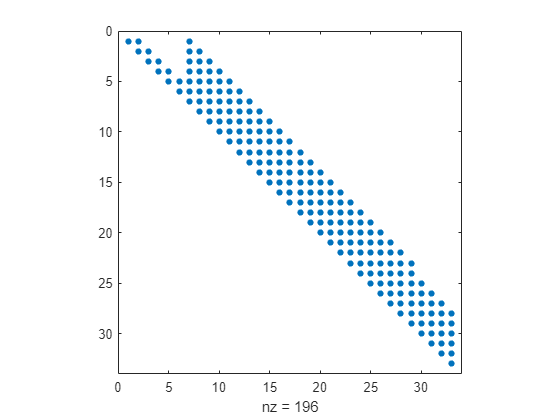

figure;spy(A1);title('A1')

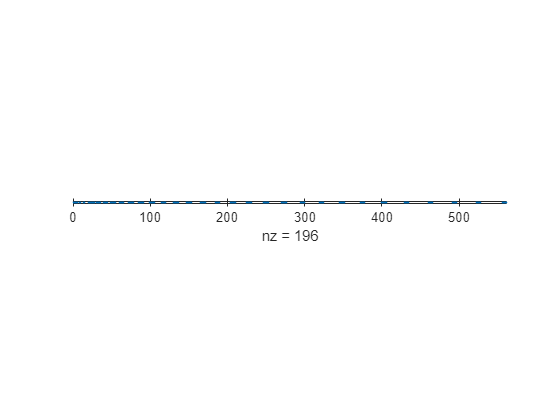

figure;spy(A2);title('A2')

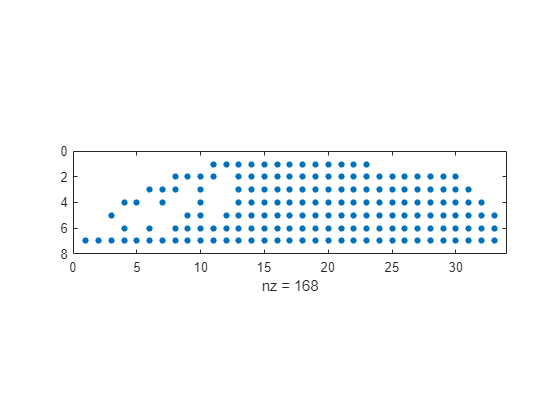

figure;spy(A_band_CHOL);title('A_band_CHOL')

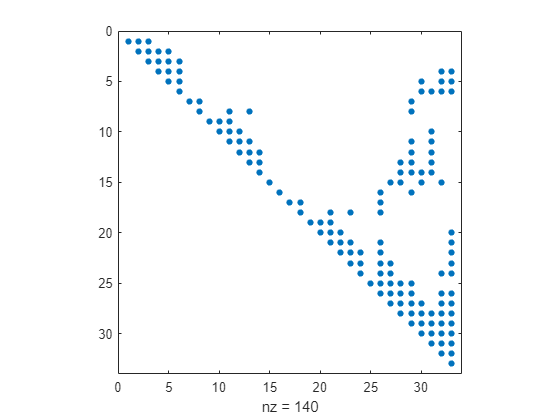

figure;spy(A4);title('A4')

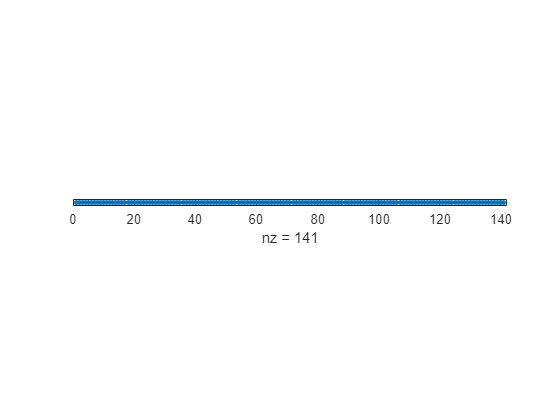

figure;spy(A_csr);title('A_csr')

figure;spy(A_RCM)